clear
A=sym([0 0])

$$A = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

B=sym([1 3])

$$B = \left(\begin{array}{cc} 1 & 3 \end{array}\right)$$

C=sym([7 1])

$$C = \left(\begin{array}{cc} 7 & 1 \end{array}\right)$$

hold on
plot(A(1),A(2),'ro')
plot(B(1),B(2),'go')
plot(C(1),C(2),'bo')
grid
Lab=line2p(A,B)

$$Lab = 3\,x=y$$

Lbc=line2p(B,C)

$$Lbc = x+3\,y=10$$

kab=sym(3),kcd=kab

$$kab = 3$$

$$kcd = 3$$

kbc=sym(-1/3),kad=kbc

$$kbc = -\frac{1}{3}$$

$$kad = -\frac{1}{3}$$

kab*kbc

$$ans = -1$$

% AB и BC ортогональны

% Достраиваем недостающие стороны
Lcd=linekp(kcd,C)

$$Lcd = 3\,x=y+20$$

Lad=linekp(kad,A)

$$Lad = y=-\frac{x}{3}$$

fimplicit(Lcd)
fimplicit(Lad)
% 4-я точка
[xd,yd]=solve(Lad,Lcd);D=[xd yd]

$$D = \left(\begin{array}{cc} 6 & -2 \end{array}\right)$$

plot(D(1),D(2),'mo')
% Диагонали
Lac=line2p(A,C)

$$Lac = x=7\,y$$

Lbd=line2p(B,D)

$$Lbd = x+y=4$$

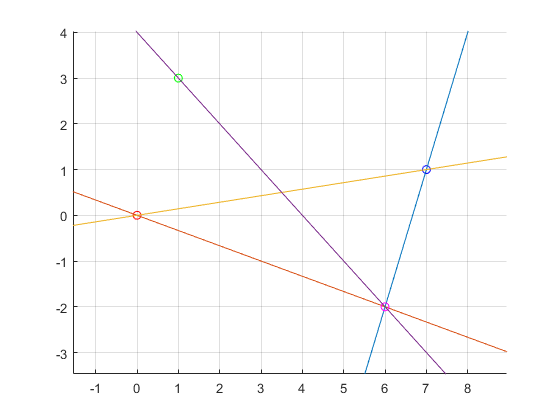

fimplicit(Lac)
fimplicit(Lbd)

xlim([-1.55 8.95])
ylim([-3.47 4.03])

% Найдем угол между диагоналями
kac=sym(1/7),k1=kac

$$kac = \frac{1}{7}$$

$$k1 = \frac{1}{7}$$

kbd=sym(-1),k2=kbd

$$kbd = -1$$

$$k2 = -1$$

alpha=atan(abs((k2-k1)/(1+k1*k2)))

$$alpha = \mathrm{atan}\left(\frac{4}{3}\right)$$

digits(3)
alpha=vpa(alpha*180/pi)

$$alpha = 53.1$$

% Вариант 2
% 4-я точка D
M=divseg2(A,C,1)

$$M = \left(\begin{array}{cc} \frac{7}{2} & \frac{1}{2} \end{array}\right)$$

D=divseg2(B,M,-2)

$$D = \left(\begin{array}{cc} 6 & -2 \end{array}\right)$$